# Rounding errors in the Vancouver Stock Exchange

In 1982, the Vancouver Stock Exchange started keeping a running index of all 1400 stocks in the exchange.  Every time a stock price changed, which happened about 2800 times a day, the index was updated and truncated to 3 decimal digits (approximately 10 binary digits: 2^10 = 1024).  The stock index was initialized to 1000.  Instead of recomputing each time, the index `y` was updated by adding the price difference `dx` divided by 1400.  After two years, the index was 480 points off.

Put the random number generator in its default state for reproducible results.

rng('default')

Average number of price changes per day.

n = 2800;

Random price changes

dx = 10*randn(n,1);

Coefficient `a` is the  the inverse of the number of stocks.

a = 1/1400;

Compute the stock index `y` as a running average by updating the stock index instead of averaging all the stock prices after every change in price.

y = zeros(n,1);
y(1) = 1000;
for k = 2:n
    y(k) = y(k-1) + a * dx(k);
end

Plot results

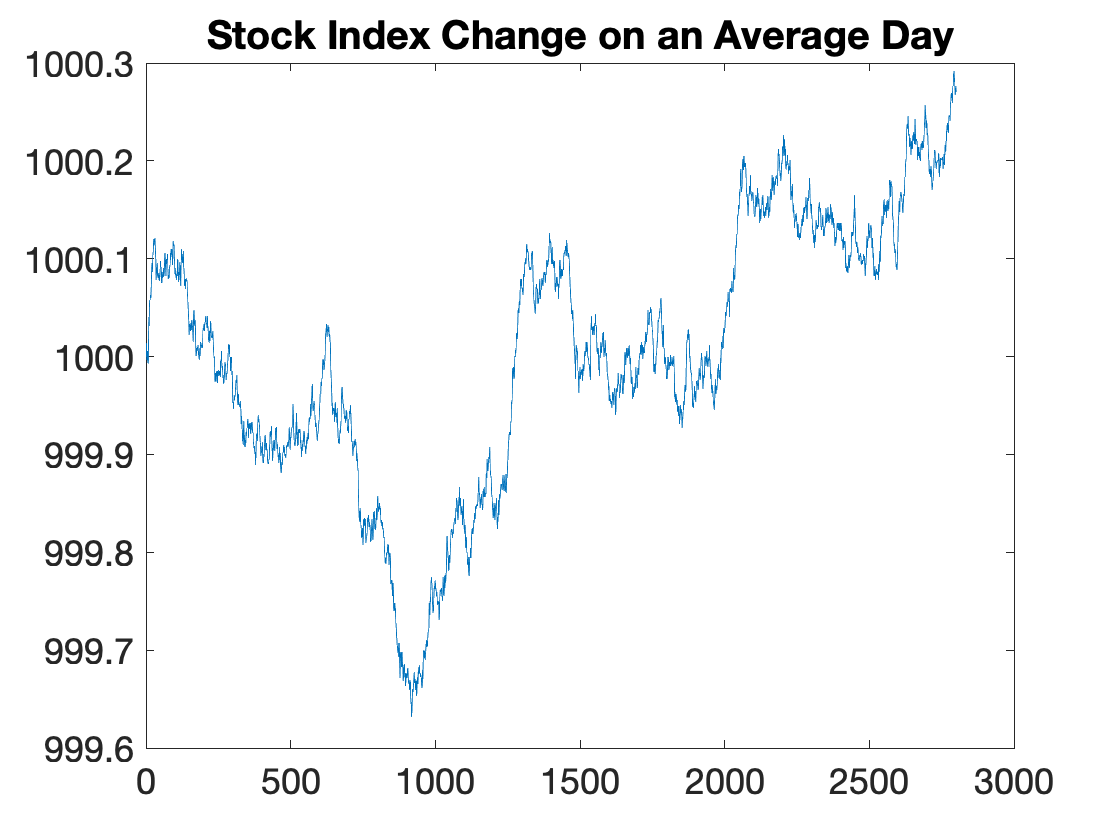

plot(y)
set(gca,'FontSize',18)
title('Stock Index Change on an Average Day')